# TMEM16a P21 Hair cells

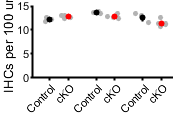

% plotting, raw data in excel document

conIHCapex = [11.82211966,12.16062839,12.51040109,12.10403306];
conIHCmid = [13.82532071,13.3511736,13.5469431];
conIHCbase = [11.46730544,13.4089984,12.46967294,12.95180457];

ckoIHCapex = [12.55186697,13.00150601,12.38740318,12.93366263];
ckoIHCmid = [12.37302486,13.38766007,12.80819725,12.99465329,12.50741719];
ckoIHCbase = [12.50607934,11.18341088,11.4172629,11.3074127,10.74687905];

conOHCapex = [40.90453402,40.08503432,39.85871975,38.7329058];
conOHCmid = [39.05046727,41.21449241,42.70232065];
conOHCbase = [37.20503542,38.79031679,37.40901883,36.79489934];

ckoOHCapex = [40.31080354,43.60921807,43.23904883,50.81081747];
ckoOHCmid = [41.72863288,41.03608847,42.20883183,43.70928834,39.55834274];
ckoOHCbase = [44.92924801,40.31913923,35.71554036,38.33488695,35.72611143];

ylbl = ('IHCs per 100 um');
ylbl2 = ('OHCs per 100 um');
dim = [1.8 1.2];
conditions = {'Control','cKO','Control','cKO','Control','cKO'};
compare6(conIHCapex,ckoIHCapex,conIHCmid,ckoIHCmid,conIHCbase,ckoIHCbase,conditions,ylbl,dim);
ylim([0 15])

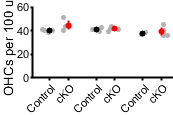


figure
compare6(conOHCapex,ckoOHCapex,conOHCmid,ckoOHCmid,conOHCbase,ckoOHCbase,conditions,ylbl2,dim);
ylim([0 60])


geno = {'con','con','con','con','con','con','con','con','con','con','con','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'}';
mouse = [1 2 3 4 1 2 3 1 2 3 4 5 6 7 8 5 6 7 8 9 5 6 7 8 9]';
location = {'apex','apex','apex','apex','middle','middle','middle','base','base','base','base','apex','apex','apex','apex','middle','middle','middle','middle','middle','base','base','base','base','base'}'; 
IHCs = [conIHCapex(1),conIHCapex(2),conIHCapex(3),conIHCapex(4),conIHCmid(1),conIHCmid(2),conIHCmid(3),conIHCbase(1),conIHCbase(2),conIHCbase(3),conIHCbase(4),ckoIHCapex(1),ckoIHCapex(2),ckoIHCapex(3),ckoIHCapex(4),ckoIHCmid(1),ckoIHCmid(2),ckoIHCmid(3),ckoIHCmid(4),ckoIHCmid(5),ckoIHCbase(1),ckoIHCbase(2),ckoIHCbase(3),ckoIHCbase(4),ckoIHCbase(5)]';

tbl = table(geno,mouse,location,IHCs,'VariableNames',{'Genotype','Mouse','Location','IHCs'})

tbl = 25×4 table
    Genotype    Mouse     Location      IHCs 
    ________    _____    __________    ______

    {'con'}       1      {'apex'  }    11.822
    {'con'}       2      {'apex'  }    12.161
    {'con'}       3      {'apex'  }     12.51
    {'con'}       4      {'apex'  }    12.104
    {'con'}       1      {'middle'}    13.825
    {'con'}       2      {'middle'}    13.351
    {'con'}       3      {'middle'}    13.547
    {'con'}       1      {'base'  }    11.467
    {'con'}       2      {'base'  }    13.409
    {'con'}       3      {'base'  }     12.47
    {'con'}       4      {'base'  }    12.952
    {'cko'}       5      {'apex'  }    12.552
    {'cko'}       6      {'apex'  }    13.002
    {'cko'}       7      {'apex'  }    12.387
    {'cko'}       8      {'apex'  }    12.934
    {'cko'}       5      {'middle'}    12.373


lme = fitlme(tbl,'IHCs~Genotype+(1|Location)+(1|Mouse)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations              25
    Fixed effects coefficients           2
    Random effects coefficients         12
    Covariance parameters                3

Formula:
    IHCs ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    61.756    67.851    -25.878          51.756  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat     DF    pValue        Lower       Upper   
    {'(Intercept)' }          12.739     0.3159    40.327    23    7.5888e-23      12.086      13.393
    {'Genotype_cko'}        -0.45077    0.24946    -1.807    23      0.083868    -0.96681    0.065282

Random effects covariance parameters (95% CIs):
Group: Location (3 Levels)
    Name1                  Name2                  Type


OHCs = [conOHCapex(1),conOHCapex(2),conOHCapex(3),conOHCapex(4),conOHCmid(1),conOHCmid(2),conOHCmid(3),conOHCbase(1),conOHCbase(2),conOHCbase(3),conOHCbase(4),ckoOHCapex(1),ckoOHCapex(2),ckoOHCapex(3),ckoOHCapex(4),ckoOHCmid(1),ckoOHCmid(2),ckoOHCmid(3),ckoOHCmid(4),ckoOHCmid(5),ckoOHCbase(1),ckoOHCbase(2),ckoOHCbase(3),ckoOHCbase(4),ckoOHCbase(5)]';
tbl = table(geno,mouse,location,OHCs,'VariableNames',{'Genotype','Mouse','Location','OHCs'})

tbl = 25×4 table
    Genotype    Mouse     Location      OHCs 
    ________    _____    __________    ______

    {'con'}       1      {'apex'  }    40.905
    {'con'}       2      {'apex'  }    40.085
    {'con'}       3      {'apex'  }    39.859
    {'con'}       4      {'apex'  }    38.733
    {'con'}       1      {'middle'}     39.05
    {'con'}       2      {'middle'}    41.214
    {'con'}       3      {'middle'}    42.702
    {'con'}       1      {'base'  }    37.205
    {'con'}       2      {'base'  }     38.79
    {'con'}       3      {'base'  }    37.409
    {'con'}       4      {'base'  }    36.795
    {'cko'}       5      {'apex'  }    40.311
    {'cko'}       6      {'apex'  }    43.609
    {'cko'}       7      {'apex'  }    43.239
    {'cko'}       8      {'apex'  }    50.811
    {'cko'}       5      {'middle'}    41.729


lme = fitlme(tbl,'OHCs~Genotype+(1|Location)+(1|Mouse)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations              25
    Fixed effects coefficients           2
    Random effects coefficients         12
    Covariance parameters                3

Formula:
    OHCs ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    133.58    139.67    -61.79           123.58  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF    pValue       Lower         Upper 
    {'(Intercept)' }        39.381      1.1466    34.344    23    2.877e-21        37.009    41.753
    {'Genotype_cko'}        2.2205      1.0777    2.0605    23     0.050834    -0.0087576    4.4498

Random effects covariance parameters (95% CIs):
Group: Location (3 Levels)
    Name1                  Name2                  Type      